# Block/batch computation

Due to communication between the memory hierarchies on a computer, the flop count is not always a good indication of how long it takes to do a computation. Here's an example with the simplest kind of operation --- matrix multiplication --- and it shows that we can often solve several problems for the cost of solving a single problem. That is, we can multiply $Y=A[x_1,\ldots,x_k]$ for about the same cost as $Y=Ax_1$.

Stephen Becker, June 11 2018

% Do the actual computation 
n   = 5e3;
A   = randn(n);
X   = randn(n);

blockSizes  = [1, 5, 10, 20, 100, 1e3, 5e3 ];
times       = zeros( length(blockSizes), 1 );

for i   = 1:length(blockSizes)
    fprintf('i is %d\n', i );
    block   = blockSizes( i );
    if block < 1e2
        reps    = round( 1e2/block );
    elseif block < 1e3
        reps    = round( 1e3/block );
    else
        reps    = round( 1e4/block );
    end
    % to get accurate timing, we'll repeat this
    t1 = tic;
    for trial = 1:reps
        y   = A*X(:,1:block);
    end
    tm  = toc(t1);
    tm  = tm/reps;
    times(i)    = tm;
end

i is 1
i is 2
i is 3
i is 4
i is 5
i is 6
i is 7


## Display results

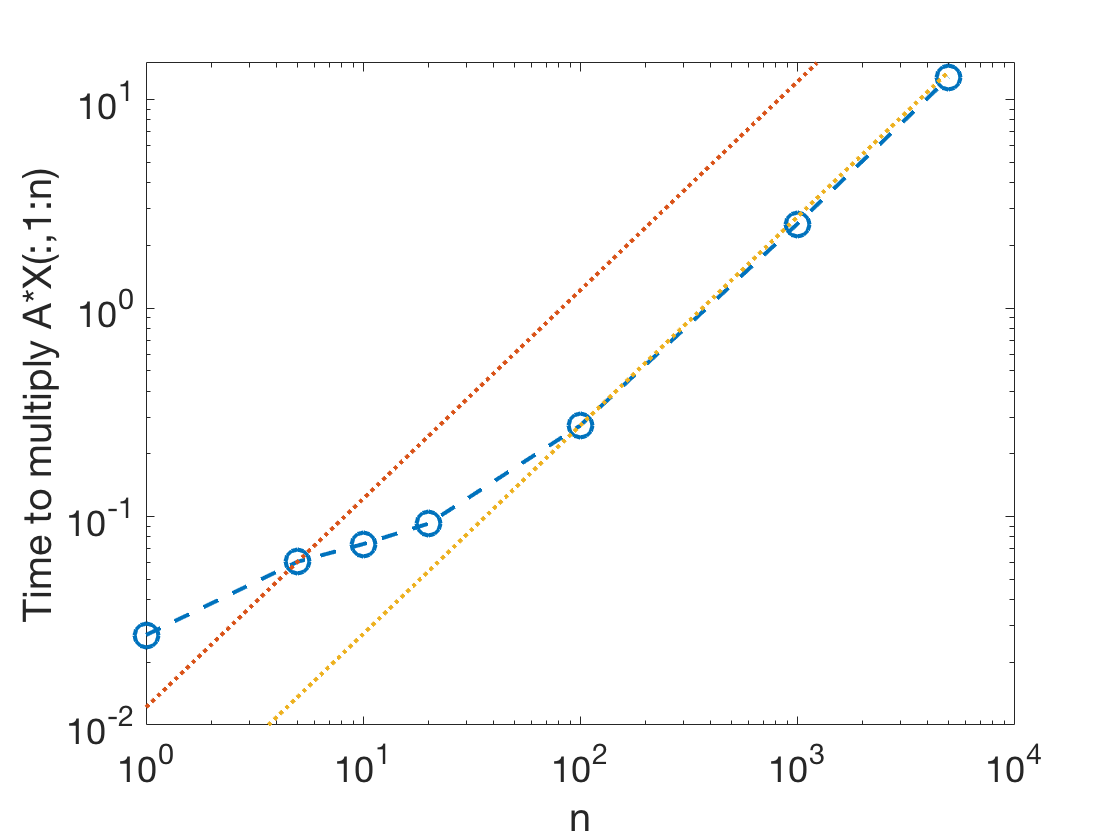

figure(1); clf;
loglog( blockSizes, times, 'o--','markersize',12,'linewidth',2 )
set(gca,'fontsize',18);
xlabel('n');
ylabel('Time to multiply A*X(:,1:n)');
hold all
loglog( blockSizes, blockSizes*times(2)/blockSizes(2), ':','linewidth',2  )
loglog( blockSizes, blockSizes*times(5)/blockSizes(5), ':','linewidth',2  )
ylim([1e-2,15]);

% To put it another way,
fprintf('For an increase in flop count of %gx,\n  we only required %.1fx more time',...
    blockSizes(4)/blockSizes(2),times(4)/times(2))

For an increase in flop count of 4x,
  we only required 1.5x more time

## Display them another way

Suppose we did all $n$ multiplications, but grouped then into blocks of size $b$. How long would this take?

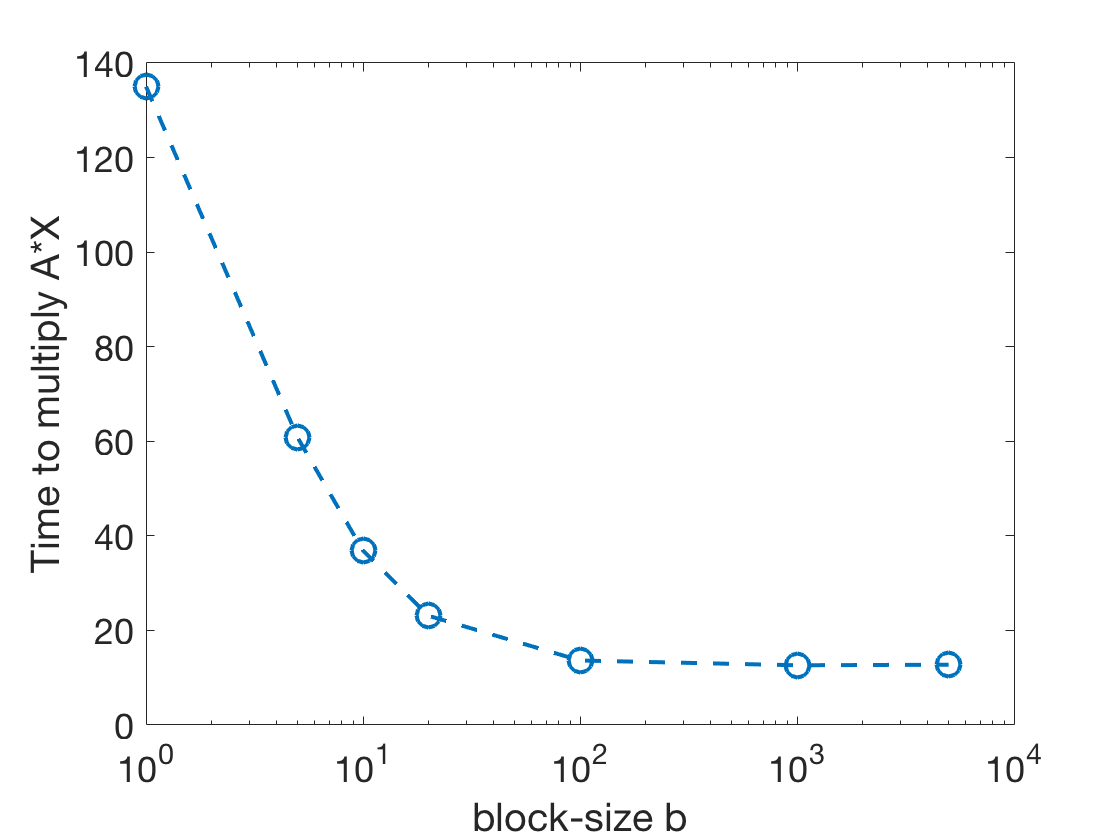

figure(2); clf;
semilogx( blockSizes, times.*(n./blockSizes'), 'o--','markersize',12,'linewidth',2 )
set(gca,'fontsize',18);
xlabel('block-size b');
ylabel('Time to multiply A*X');
hold all